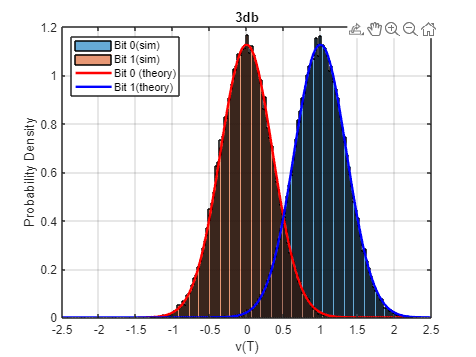

close all; clc;
%%parameter
data_number = 10^5; % # of bits 
EbN0dB_vec = 3 ;% Eb/N0 in dB 
Fs=10; % sampling frequency (used to generate received samples
%% transmitter
Data_bit=(rand(1,data_number) > 0.5 ); % random bits
p1=ones(1,Fs);% discrete‐time rectangular pulse that represents on
Data_pulse_array=(p1.')*Data_bit;
Data_pulse=reshape(Data_pulse_array,1,length(p1)*data_number);
%% AWGN channel
EbN0dB = EbN0dB_vec; 
EbN0 = 10^(EbN0dB/10); % EbN0 is now in linear scale
sgma = sqrt( 0.5/EbN0/2*10 );
num1=0;
num0=0;
for eig=1:1000000
    if Data_pulse(eig)==1
        num1=num1+1;
    else
        num0=num0+1;
    end
end
bit1=ones(1,num1)+normrnd(0, sgma, a, num1 ) ;
bit0=zeros(1,num0)+normrnd(0, sgma, a, num0 );
b1_filtered=conv(bit1,p1);% MF output
b1_demapping=b1_filtered(10:10:end)/10;
b0_filtered=conv(bit0,p1);% MF output
b0_demapping=b0_filtered(10:10:end)/10;
b1_h=histogram(b1_demapping,'Normalization','pdf');
hold on
b0_h=histogram(b0_demapping,'Normalization','pdf');
xlim([-2.5 2.5])
hold on
x = -2.5:.01:2.5;
ave0 = normpdf(x,0,sgma/sqrt(10));
ave1 = normpdf(x,1,sgma/sqrt(10));
plot(x,ave0,'r','LineWidth',2)
hold on
plot(x,ave1,'b','LineWidth',2)
legend('Bit 0(sim)','Bit 1(sim)','Bit 0 (theory)','Bit 1(theory)','Location','northwest')
grid on
title('3db')
xlabel('v(T)')
ylabel('Probability Density')

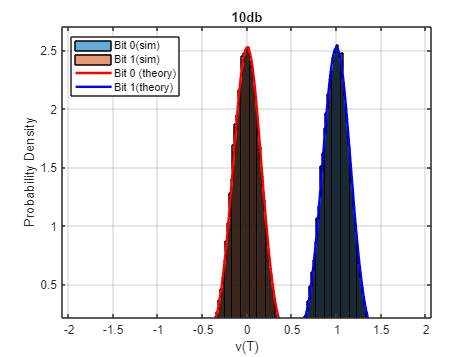

close all;clc;
%%parameter
data_number = 10^5; % # of bits 
EbN0dB_vec = 10 ;% Eb/N0 in dB 
Fs=10; % sampling frequency (used to generate received samples
%% transmitter
Data_bit=(rand(1,data_number) > 0.5 ); % random bits
p1=ones(1,Fs);% discrete‐time rectangular pulse that represents on
Data_pulse_array=(p1.')*Data_bit;
Data_pulse=reshape(Data_pulse_array,1,length(p1)*data_number);
%% AWGN channel
EbN0dB = EbN0dB_vec; 
EbN0 = 10^(EbN0dB/10); % EbN0 is now in linear scale
sgma = sqrt( 0.5/EbN0/2*10 );
num1=0;
num0=0;

for eig=1:1000000
    if Data_pulse(eig)==1
        num1=num1+1;
    else
        num0=num0+1;
    end
end
bit1=ones(1,num1)+normrnd(0, sgma, a, num1 ) ;
bit0=zeros(1,num0)+normrnd(0, sgma, a, num0 );
b1_filtered=conv(bit1,p1);% MF output
b1_demapping=b1_filtered(10:10:end)/10;
b0_filtered=conv(bit0,p1);% MF output
b0_demapping=b0_filtered(10:10:end)/10;
b1_h=histogram(b1_demapping,'Normalization','pdf');
hold on
b0_h=histogram(b0_demapping,'Normalization','pdf');
xlim([-2.5 2.5])
hold on
x = -2.5:.01:2.5;
ave0 = normpdf(x,0,sgma/sqrt(10));
ave1 = normpdf(x,1,sgma/sqrt(10));
plot(x,ave0,'r','LineWidth',2)
hold on
plot(x,ave1,'b','LineWidth',2)
legend('Bit 0(sim)','Bit 1(sim)','Bit 0 (theory)','Bit 1(theory)','Location','northwest')
grid on
title('10db')
xlabel('v(T)')
ylabel('Probability Density')